# Feedback Linearization

Feedback linearization is one of the most fundamental methods in nonlinear control theory, and is the basis for more complex methods. Feedback linearization can operate on the system state or on a set of outputs; in general, it looks to cancel out nonlinearities in the dynamics and replace them with the desired linear dynamics. While theoretically powerful, feedback linearization can struggle in practice as it requires very precise model knowledge.

There are several related methods which cancel out only part of the nonlinear dynamics, such as PD + Gravity compensation in robotics, which cancels the effect of gravity and then applies PD control at joints. These methods often trade off control authority for requiring less model knowledge.

clear; clc; close all;
addpath("../Models")
addpath("../Simulators/")

## Feedback Linearization for the Inverted Pendulum

The pendulum has dynamics


$$\left[ \matrix{\dot{\theta} \cr \ddot{\theta}}\right] = \left[\matrix{\dot{\theta} \cr -\frac{g}{L}\sin \theta} \right] + \left[\matrix{ 0 \cr \frac{1}{mL^2}} \right] \tau = f(x) + g(x)u $$


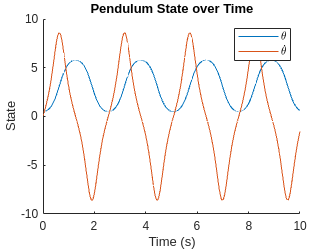

m = 1; g = 9.81; L = 0.5;
params.m = m; params.g = g; params.L = L;

no_ctrl = @(x) 0;
[t, x, ~] = continuousSim(@pendulum, no_ctrl, [0, 10], [0.5, 0], params);
figure;
hold on;
plot(t, x(:, 1))
plot(t, x(:, 2))
xlabel('Time (s)')
ylabel('State')
legend({'$\theta$', '$\dot{\theta}$'}, 'Interpreter', 'latex')
hold off
title('Pendulum State over Time')

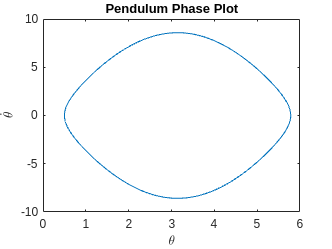


figure;
plot(x(:, 1), x(:, 2))
xlabel('$\theta$', 'Interpreter', 'latex')
ylabel('$\dot{\theta}$', 'Interpreter', 'latex')
title('Pendulum Phase Plot')

Consider an output, $y = \theta$; the control objective is to drive this output to zero exponentially. Computing derivatives of the output


$$\dot{y} = \dot{\theta} \\
\ddot{y} = \ddot{\theta} = \frac{g}{L}\sin \theta + \frac{1}{mL^2}\tau$$


This output is 'relative degree 2', since the output does not appear until the second derivative. If we choose the control law


$$\tau = mL^2\left(\frac{g}{L}\sin\theta -K_p y - K_d \dot{y}\right)$$


the output dynamics become


$$\left[\matrix{\dot{y} \cr \ddot{y}}\right] = \left[ \matrix{0 & 1 \cr -K_p & -K_d}\right]\left[\matrix{y \cr \dot{y}}\right]$$


Which is an exponentially stable linear system for properly chosen gains.

F = [0 1; 0 0];
G = [0; 1];
Q = eye(2);
R = 1;
K = lqr(F, G, Q, R);

fdblin_ctrl = @(x) m*L^2 *(-g/L*sin(x(1, :)) -K*x);

We can now test this controller on the full nonlinear pendulum dynamics. 

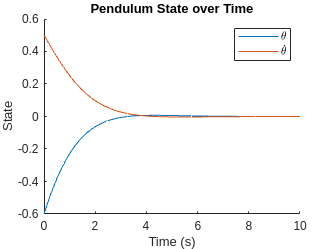

theta0 =-0.6;
thetadot0 = 0.5;

t0 = 0; tf = 10;
x0 = [theta0; thetadot0];
[t, x, u] = continuousSim(@pendulum, fdblin_ctrl, [t0, tf], x0, params);

figure;
hold on;
plot(t, x(:, 1))
plot(t, x(:, 2))
xlabel('Time (s)')
ylabel('State')
legend({'$\theta$', '$\dot{\theta}$'}, 'Interpreter', 'latex')
hold off
title('Pendulum State over Time')

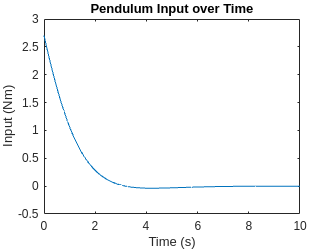


figure;
plot(t, u)
xlabel('Time (s)')
ylabel('Input (Nm)')
title('Pendulum Input over Time')

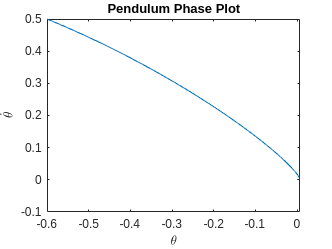


figure;
plot(x(:, 1), x(:, 2))
xlabel('$\theta$', 'Interpreter', 'latex')
ylabel('$\dot{\theta}$', 'Interpreter', 'latex')
title('Pendulum Phase Plot')

Examining the plots, the system behaves 'much less' like a pendulum, precisely because its nonlinear dynamics are gone; they have been canceled and replaced by linear dynamics. 

More interesting behavior can be done by tracking an output which is a function of state $y = h(x)$, or a function of time, $y = h(x, t)$. In the following example, we track a reference trajectory of $\theta = \sin t$. 


$$e = \theta - \sin t \\
\dot{e} = \dot{\theta} - \cos t \\
\ddot{e} = \ddot{\theta} + \sin t = -\frac{g}{L}\sin\theta + \frac{1}{mL^2}\tau + \sin t$$


Choosing a feedback law


$$\tau = mL^2\left(\frac{g}{L}\sin\theta - \sin t - K_p(\theta - \sin t) - K_d(\dot{\theta} - \cos t)\right)$$


Renders the error dynamics


$$\left[\matrix{\dot{e} \cr \ddot{e}}\right] = \left[ \matrix{0 & 1 \cr -K_p & -K_d}\right]\left[\matrix{e \cr \dot{e}}\right]$$


exponentially stable. 

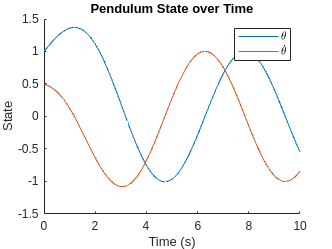

fdblin_traj = @(x, t) m*L^2*(-g/L*sin(x(1, :)) - sin(t) - K * [x(1, :) - sin(t); x(2, :) - cos(t)]);

th0 =1;
thdot0 = 0.5;


t0 = 0; tf = 10;

x0 = [th0; thdot0];
[t, x, u] = continuousSim(@pendulum, fdblin_traj, [t0, tf], x0, params);

figure;
hold on;
plot(t, x(:, 1))
plot(t, x(:, 2))
xlabel('Time (s)')
ylabel('State')
legend({'$\theta$', '$\dot{\theta}$'}, 'Interpreter', 'latex')
hold off
title('Pendulum State over Time')

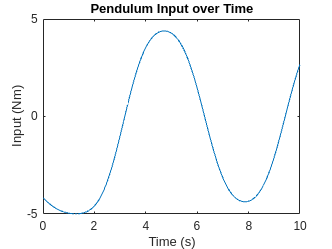


figure;
plot(t, u)
xlabel('Time (s)')
ylabel('Input (Nm)')
title('Pendulum Input over Time')

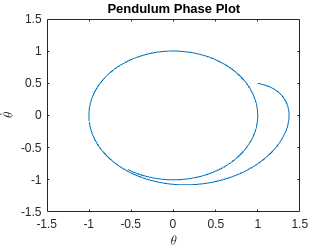


figure;
plot(x(:, 1), x(:, 2))
xlabel('$\theta$', 'Interpreter', 'latex')
ylabel('$\dot{\theta}$', 'Interpreter', 'latex')
title('Pendulum Phase Plot')

Again, the output tracks quite well. Feedback linearization is a miracle worker for trajectory tracking in simulation, when all of your dynamics are known perfectly.

## Feedback Linearization for Cartpole

The pendulum is perhaps the simplest nonlinear system, and it is *fully actuated*, it has an actuator for every degree of freedom. Turing to the cartpole, we have only one actuator but two degrees of freedom; therefore, we will not be able to make the system state follow arbitrary smooth curves as we could with the pendulum. The cartpole has dynamics


$$\left[\matrix{\dot{x} \cr \dot{\theta} \cr \ddot{x} \cr \ddot{\theta}}\right] = \left[\matrix{\dot{x} \cr \dot{\theta} \cr  \frac{-mL\sin\theta\dot{\theta}^2+mg\sin\theta\cos\theta}{M+m(1-\cos^2{\theta}) \cr \frac{-mL\sin\theta\cos\theta \dot{\theta}^2+(M+m)g\sin\theta}{(M+m(1-\cos^2{\theta}))L}}\right] + \left[ \matrix{0 \cr 0 \cr  \frac{1}{M+m(1-\cos^2{\theta})\cr \frac{\cos\theta}{(M+m(1-\cos^2{\theta}))L}}\right]u$$


Again, consider a relative degree 2 output on the cartpole, for instance $y=\theta$, stabilizing the pendulum upright. Computing derivatives of the output


$$\dot{y} = \dot{\theta} \\
\ddot{y} = \ddot{\theta} = 
\frac{-mL\sin\theta\cos\theta \dot{\theta}^2+(M+m)g\sin\theta}{(M+m(1-\cos^2{\theta}))L} +\frac{\cos\theta}{(M+m(1-\cos^2{\theta}))L}u$$


Choosing the output


$$u = \frac{(M+m(1-\cos^2{\theta}))L}{\cos\theta} \left(-\frac{-mL\sin\theta\cos\theta \dot{\theta}^2+(M+m)g\sin\theta}{(M+m(1-\cos^2{\theta}))L} - K_p \theta - K_d \dot{\theta}\right)$$


Renders the output dynamics


$$\left[\matrix{\dot{y} \cr \ddot{y}}\right] = \left[ \matrix{0 & 1 \cr -K_p & -K_d}\right]\left[\matrix{y \cr \dot{y}}\right]$$


Which is an exponentially stable linear system for the correct choice of gains. Importantly, this choice of output is not feedback linearizable over the whole state space; if $\theta = \pm \pi / 2$, the division by $\cos\theta$ in the control law blows up to infinity; the controller is only well defined away from this singularity.

F = [0 1; 0 0];
G = [0; 1];
Q = eye(2);
R = 1;
Kcp = lqr(F, G, Q, R);

m_cp = 1; M_cp = 1; L_cp = 1; g_cp = 9.81;
params_cp.m = m_cp; params_cp.M = M_cp;
params_cp.g = g_cp;params_cp.L = L_cp;

fdblin_ctrl_cp = @(x) ((M_cp+m_cp*(1-cos(x(2, :)).^2))*L_cp)./ cos(x(2, :)) .*...
    (-(-m_cp*L_cp*sin(x(2, :)).*cos(x(2, :)).*x(4, :).^2 + ((M_cp+m_cp)*g*sin(x(2, :))))./((M_cp+m_cp*(1-cos(x(2, :)).^2))*L_cp) - Kcp * [x(2, :); x(4, :)]);

And simulating on the cartpole dynamics

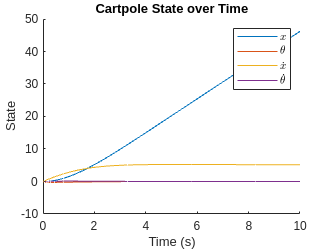

th0cp =-0.3;
thdot0cp = 0;
x0 = 0;
xdot0 = 0;
y0 = [x0; th0cp; xdot0; thdot0cp];
[tcp, xcp, ucp] = continuousSim(@cartpole, fdblin_ctrl_cp, [t0, tf], y0, params_cp);

figure;
hold on;
plot(tcp, xcp(:, 1))
plot(tcp, xcp(:, 2))
plot(tcp, xcp(:, 3))
plot(tcp, xcp(:, 4))
xlabel('Time (s)')
ylabel('State')
legend({'$x$', '$\theta$', '$\dot{x}$', '$\dot{\theta}$'}, 'Interpreter', 'latex')
hold off
title('Cartpole State over Time')

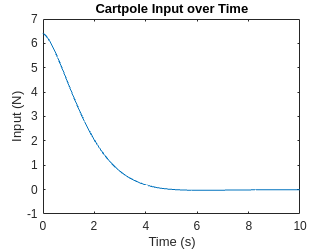


figure;
plot(tcp, ucp)
xlabel('Time (s)')
ylabel('Input (N)')
title('Cartpole Input over Time')

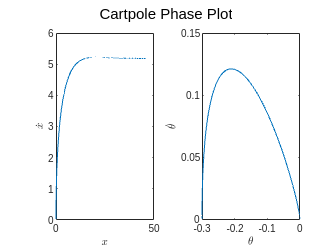


figure;
subplot(1, 2, 1)
plot(xcp(:, 1), xcp(:, 3))
xlabel('$x$', 'Interpreter', 'latex')
ylabel('$\dot{x}$', 'Interpreter', 'latex')
subplot(1, 2, 2)
plot(xcp(:, 2), xcp(:, 4))
xlabel('$\theta$', 'Interpreter', 'latex')
ylabel('$\dot{\theta}$', 'Interpreter', 'latex')
sgtitle('Cartpole Phase Plot')

Note that while the $\theta$ dynamics are stabilized to 0 nicely, the resulting $x$ dynamics drift off to infinity. This is a fundamental problem with underactuated systems. However, recall that the LQR controller derived from the linearized dynamics in the 'Linearization' script was able to stablize both the angle and position to zero; however, this controller was only valid locally. It is possible to stabilize the angle and position to zero using nonlinear control, but it requires the design of a trajectory in which the underactuated coordinates have desirable behavior. This can be done using trajectory optimization or MPC. Output feedback linearization works well for systems with perfectly known dynamics where any underactuation is not relevant or has been handled by a trajectory planner. It is not a tool which handles underactuation.

## Limitations of Feedback Linearization

Feedback linearization has many drawbacks an limitations. For instance, it is quiet fragile to unmodeled or uncertain dynamics. Additionally, it can use significant unnecesary energy to dominate the nonlinear dynamics and replace them with the linear ones. In many cases, the system may be designed so that the nonlinear dynamics have some desirable properties; spending energy to cancel these properties is undesirable. It also does not easily allow constraints (input or state) to be incorporated into the control problem. 

While energy consumption will be investigated later (in comparison with CLF-QP controllers), we will take a brief look here at the impact of uncertainty in the dynamics of the system. Consider the pendulum, but with the 1% increases in mass and length parameters:


$$m'=1.01m \\
L' = 1.01L$$


Additionally, assume that the measurment of the angle of the pendulum is off by $1^\circ$. Using the same feedback linearization controller to stabilize the pendulum to the upright position:

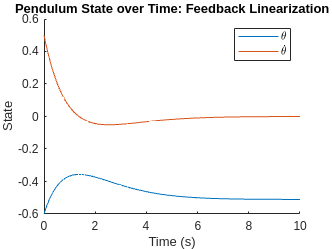

% Modify system parameters
m_ = 1.01*m; g = 9.81; L_ = 1.01*L;
params_.m = m_; params_.g = g; params_.L = L_;
% Modify the measurement of theta by 1deg.
angle_pert = 1;

fdblin_ctrl_ = @(x) m*L^2 *(-g/L*sin(x(1, :) + deg2rad(angle_pert)) -K*[x(1, :) + deg2rad(angle_pert); x(2, :)]);

theta0 =-0.6;
thetadot0 = 0.5;


t0 = 0; tf = 10;

x0 = [theta0; thetadot0];
[t, x, u] = continuousSim(@pendulum, fdblin_ctrl_, [t0, tf], x0, params_);

figure;
hold on;
plot(t, x(:, 1))
plot(t, x(:, 2))
xlabel('Time (s)')
ylabel('State')
legend({'$\theta$', '$\dot{\theta}$'}, 'Interpreter', 'latex')
hold off
title('Pendulum State over Time: Feedback Linearization')

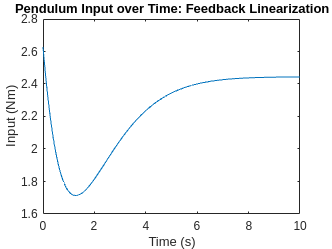


figure;
plot(t, u)
xlabel('Time (s)')
ylabel('Input (Nm)')
title('Pendulum Input over Time: Feedback Linearization')

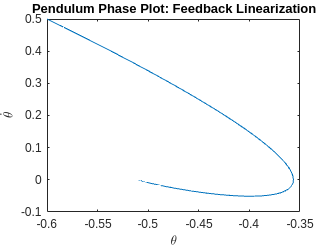


figure;
plot(x(:, 1), x(:, 2))
xlabel('$\theta$', 'Interpreter', 'latex')
ylabel('$\dot{\theta}$', 'Interpreter', 'latex')
title('Pendulum Phase Plot: Feedback Linearization')


fprintf("Steady State Error: %0.4f", x(end, 1))

Steady State Error: -0.5102

Compare this performance to the performance of the PD controller based on the linearized dynamics.

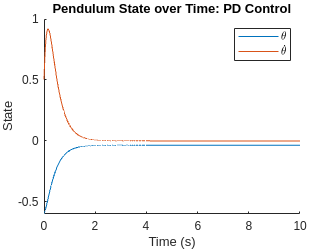

Apend = [0 1; g/L 0];
Bpend = [0; 1 / (m * L^2)];

Qp = eye(2);
Rp = 1;

Kp = lqr(Apend, Bpend, Qp, Rp);

ctrl = @(x) - Kp * [x(1, :) + deg2rad(angle_pert); x(2, :)];
[t, x] = continuousSim(@pendulum, ctrl, [t0, tf], x0, params_);

figure;
hold on;
plot(t, x(:, 1))
plot(t, x(:, 2))
xlabel('Time (s)')
ylabel('State')
legend({'$\theta$', '$\dot{\theta}$'}, 'Interpreter', 'latex')
hold off
title('Pendulum State over Time: PD Control')

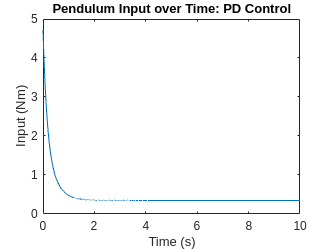


figure;
plot(t, -Kp * x')
xlabel('Time (s)')
ylabel('Input (Nm)')
title('Pendulum Input over Time: PD Control')

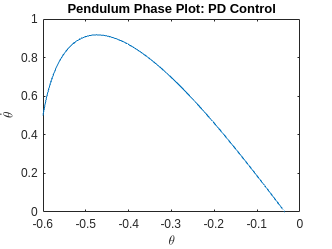


figure;
plot(x(:, 1), x(:, 2))
xlabel('$\theta$', 'Interpreter', 'latex')
ylabel('$\dot{\theta}$', 'Interpreter', 'latex')
title('Pendulum Phase Plot: PD Control')


fprintf("Steady State Error: %0.4f", x(end, 1))

Steady State Error: -0.0352

Because the nonlinear dynamics are not being cancelled perfectly, extra terms remain in the dynamics and lead to much extra steady state error (over 0.5 radian for feedback control compared to less than 0.05 radians for PD control). The PD controller based on the nonlinear dynamics behaves much better, as it is completely model independent (the gain design depends on the model, but the implementation of the controller does not). The PD controller only has any steady state error because the measurment of the angle is off. 